% AAE 567 Final Exam Spring 2021 Problem 4
% Tomoki Koike

% Housekeeping commands
clear all; close all; clc;

% Define system matrices 
A = [0 1 0 0; 0 -0.2 3 0; 0 0 0 1; 0 -0.5 30 0];
B0 = [0 0; 0.25 0; 0 0; 0 0.1];
B1 = [0; 1; 0; 5];
C = [1 0 0 0; 0 0 1 0];
D = [0.25 0; 0 0.05];

% Obtain the K gain with LQR
K = lqr(A, B1, diag([1,2,4,2]), diag([0.1]));
sym(K)

$$ans = \left(\begin{array}{cccc} -3.1623 & -7.3031 & 24.8433 & 6.9672 \end{array}\right)$$


% Find L gain
rank(obsv(A,C))

ans = 4

rank(ctrb(A,B0))

ans = 4

P = are(A', C'*inv(D*D')*C, B0*B0');
sym(P)

$$ans = \left(\begin{array}{cccc} 0.0792 & 0.0505 & 0.0013 & 0.0025\\ 0.0505 & 0.0771 & 0.0133 & 0.0668\\ 0.0013 & 0.0133 & 0.0273 & 0.1490\\ 0.0025 & 0.0668 & 0.1490 & 0.8152 \end{array}\right)$$

L = P*C'*inv(D*D');
sym(L)

$$ans = \left(\begin{array}{cc} 1.2671 & 0.5179\\ 0.8081 & 5.3104\\ 0.0207 & 10.9191\\ 0.0400 & 59.6184 \end{array}\right)$$


% Check the eigenvalues
sym([eig(A-B1*K); eig(A-L*C)])

$$ans = \left(\begin{array}{c} -23.9934\\ -0.8102\\ -1.4647+0.5430\,\mathrm{i}\\ -1.4647-0.5430\,\mathrm{i}\\ -0.7126+0.7022\,\mathrm{i}\\ -0.7126-0.7022\,\mathrm{i}\\ -5.4805+0.1759\,\mathrm{i}\\ -5.4805-0.1759\,\mathrm{i} \end{array}\right)$$


% System matrices for the actual states
As = A;
Bs = [B0, B1];
Cs = eye(4);
Ds = zeros(size(Cs,1), size(Bs,2));

% System matrices for the steady state Kalman filter states
Akf = A - L*C;
Bkf = [L, B1];
Ckf = eye(4);
Dkf = zeros(size(Ckf,1), size(Bkf,2));

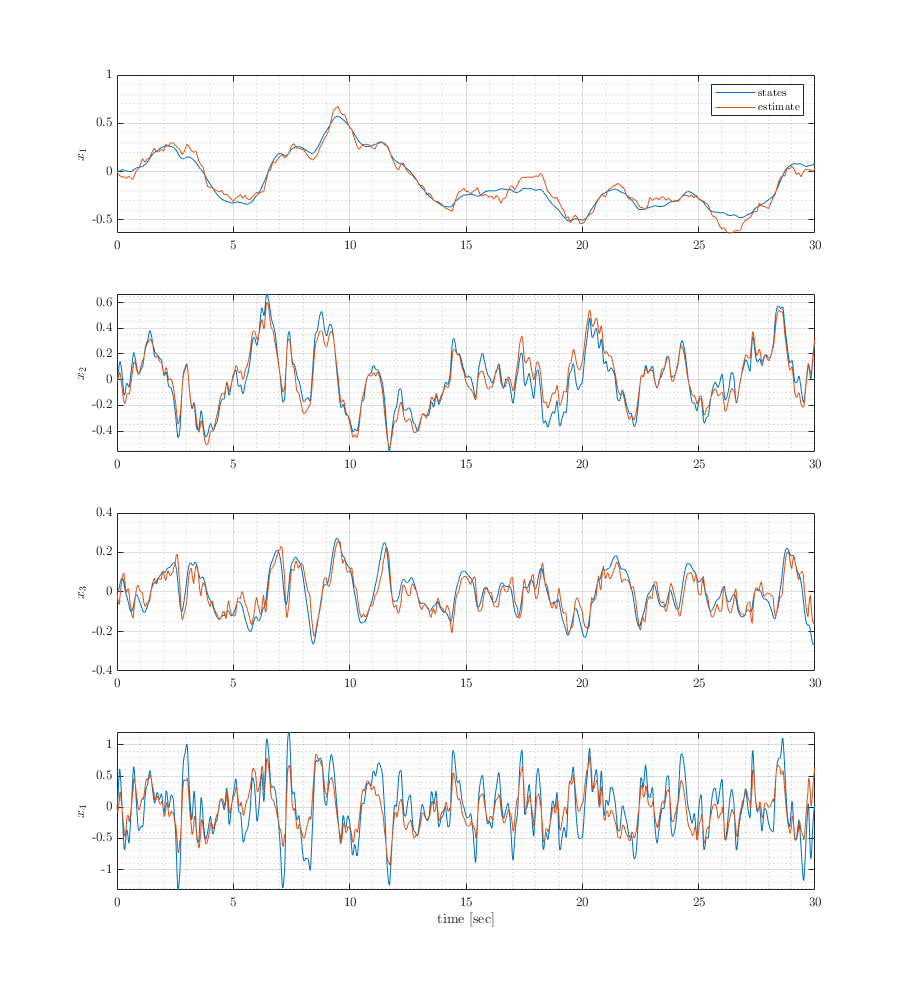

% Plotting results 
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');

% Simulate 
simout = sim('final_p4_ssKF.slx');

% Data rendering 
xs = simout.states.signals.values;
xkf = simout.estimations.signals.values;
t  = simout.tout;

% Plot 
fig = figure("Renderer","painters","Position",[60 60 900 1000]);
    subplot(4,1,1)
    plot(t, xs(:,1))
    grid on; grid minor; box on; hold on;
    plot(t, xkf(:,1))
    hold off;
    ylabel('$x_1$')
    legend('states', 'estimate')
    
    subplot(4,1,2)
    plot(t, xs(:,2))
    grid on; grid minor; box on; hold on;
    plot(t, xkf(:,2))
    hold off;
    ylabel('$x_2$')
    
    subplot(4,1,3)
    plot(t, xs(:,3))
    grid on; grid minor; box on; hold on;
    plot(t, xkf(:,3))
    hold off;
    ylabel('$x_3$')
    
    subplot(4,1,4)
    plot(t, xs(:,4))
    grid on; grid minor; box on; hold on;
    plot(t, xkf(:,4))
    hold off;
    ylabel('$x_4$')
    xlabel('time [sec]')
saveas(fig, 'final_p4_plot.png')